# Actividad 8.2

### Diego Garcia Rueda

#### **Obtener **la matriz de  transformación **homogénea  T  **de los siguientes sistemas la cual relacione la posición y orientación del extremo del robot respecto a su sistema de referencia fijo (la base).

Primero se realizan los comandos de limpieza de pantalla y de workspace.

clear all
close all
clc

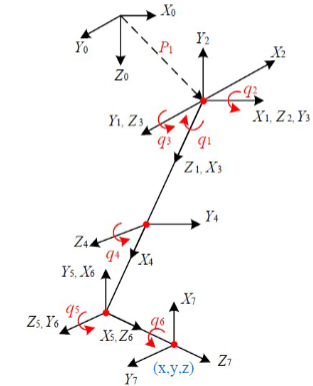

Se calculan las matrices de transformación Homogénea del modelo, en este modelo todas las traslaciones entre las rotaciones tienen un valor de 2.

m3_H0 = SE3;
%Operaciones de Junta 1 a junta 2
m3_H1 = SE3(roty(pi/2), [0,0,0]);
m3_H2 = SE3(rotz(-pi/2), [0,0,0]);

%Operaciones de Junta 2 a junta 3
m3_H3 = SE3(roty(-pi/2), [0,0,0]);
m3_H4 = SE3(rotz(-pi/2), [0,0,0]);

%Operaciones de Junta 3 a junta 4
m3_H5 = SE3(roty(0), [2,0,0]);

%Operaciones de Junta 4 a junta 5
m3_H6 = SE3(rotz(-pi/2), [2,0,0]);

%Operaciones de Junta 5 a junta 6
m3_H7 = SE3(rotz(pi/2), [0,0,0]);
m3_H8 = SE3(rotx(pi/2), [0,0,0]);

%Operaciones de Junta 6 a junta 7
m3_H9 = SE3(roty(0), [0,0,2]);

Se realizan las matrices de transformación globales.

m3_H20 = m3_H1 * m3_H2;
m3_H30 = m3_H20 * m3_H3;
m3_H40 = m3_H30 * m3_H4;
m3_H50 = m3_H40 * m3_H5;
m3_H60 = m3_H50 * m3_H6;
m3_H70 = m3_H60 * m3_H7;
m3_H80 = m3_H70 * m3_H8;
m3_H90 = m3_H80 * m3_H9;

Se establecen valores para los 3 ejes, estas seran las coordenadas con las traslaciones y las rotaciones de todas las transformaciones:

plot3(0, 0, 0); axis([-6 6 -6 6 -6 6]); grid on;
hold on;

Se establece la trama absoluta o global y posteriormente se realizan las animaciones para cada una de las tramas:

trplot(m3_H0,'rgb','axis', [-6 6 -6 6 -6 6])

%Primera trama
pause;
tranimate(m3_H0, m3_H1,'rgb','axis', [-6 6 -6 6 -6 6])
%Segunda trama
pause;
tranimate(m3_H1, m3_H20,'rgb','axis', [-6 6 -6 6 -6 6])
%Tercera trama
pause;
tranimate(m3_H20, m3_H30,'rgb','axis', [-6 6 -6 6 -6 6])
%Cuarta trama
pause;
tranimate(m3_H30, m3_H40,'rgb','axis', [-6 6 -6 6 -6 6])
%Quinta trama
pause;
tranimate(m3_H40, m3_H50,'rgb','axis', [-6 6 -6 6 -6 6])
%Sexta trama
pause;
tranimate(m3_H50, m3_H60,'rgb','axis', [-6 6 -6 6 -6 6])
%Septima trama
pause;
tranimate(m3_H60, m3_H70,'rgb','axis', [-6 6 -6 6 -6 6])
%Octava trama
pause;
tranimate(m3_H70, m3_H80,'rgb','axis', [-6 6 -6 6 -6 6])
%Novena trama
pause;
tranimate(m3_H80, m3_H90,'rgb','axis', [-6 6 -6 6 -6 6])



disp(m3_H40)

    0         1         0         0
    0         0         1         0
    1         0         0         0
    0         0         0         1
